%-Welcome
spm('asciiwelcome');

 ___  ____  __  __                                            
/ __)(  _ \(  \/  )                                           
\__ \ )___/ )    (   Statistical Parametric Mapping           
(___/(__)  (_/\/\_)  SPM12 - https://www.fil.ion.ucl.ac.uk/spm/



[vspm,rspm] = spm('Ver');
tlkt = ver(spm_check_version);
fprintf('%s, version %s\n',vspm,rspm);

SPM12, version 12.6


fprintf('%s, version %s\n',tlkt.Name,version);

MATLAB, version 9.13.0.2049777 (R2022b)


%-Working directory
wd = fullfile(pwd,'data');
cd(wd);

%-Input data
ref = spm_vol(fullfile(wd,'T1w.nii'));
src = spm_vol(fullfile(wd,'bold.nii'));

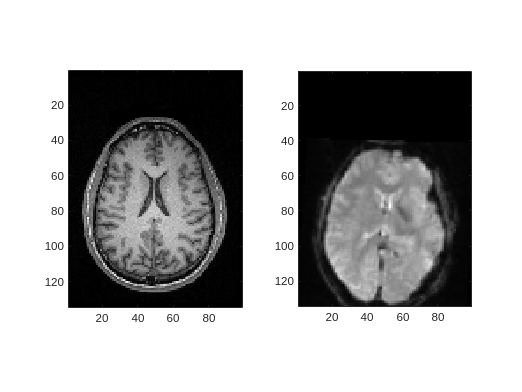

%-Display
A = spm_slice_vol(ref,spm_matrix([0 0 70]),ref.dim(1:2),1);
F = spm_slice_vol(src,src.mat\ref.mat*spm_matrix([0 0 70]),ref.dim(1:2),1);
subplot(1,2,1), imagesc(rot90(A)), axis image
subplot(1,2,2), imagesc(rot90(F)), axis image
colormap gray

%-Coregister
x = spm_coreg(ref, src);

SPM12: spm_coreg                                   10:55:38 - 18/01/2023
Completed                               :          10:55:53 - 18/01/2023


x = spm_matrix(x);

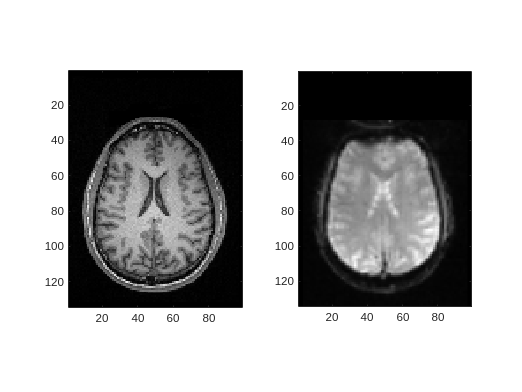

%-Display
A = spm_slice_vol(ref,spm_matrix([0 0 70]),ref.dim(1:2),1);
F = spm_slice_vol(src,x\src.mat\ref.mat*spm_matrix([0 0 70]),ref.dim(1:2),1);
subplot(1,2,1), imagesc(rot90(A)), axis image
subplot(1,2,2), imagesc(rot90(F)), axis image
colormap gray

%-Save transformation in NIfTI header and reslice
% spm_get_space(src.fname, x \ spm_get_space(src.fname));
% spm_reslice([ref,src], struct('mean',false,'which',1));